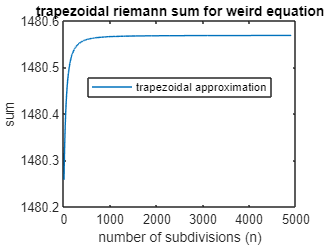

clc;
clear;
close all;

ns = 100:5000;
sums = [];

for n = ns
    sums(n-99) = TRAPsolver(n);
end

% plotting
plot(sums);
title("trapezoidal riemann sum for weird equation");
xlabel("number of subdivisions (n)");
ylabel("sum");
legend("trapezoidal approximation", location="best");

function s = TRAPsolver(n)
    delta_x = (30)/n;
    
    xl = linspace(0, 30-delta_x, n);
    xr = linspace(delta_x, 30, n);

    fxl = 200*(xl./(5+xl)).*exp(-2.*xl./30);
    fxr = 200*(xr./(5+xr)).*exp(-2.*xr./30);

    s = sum((fxl+fxr)/2*delta_x);
end

estimate for integral = 1480.57